# QEA II Final - The Gauntlet

#### Ari Porad and Jacob Smilg

#### May 2021

#### **Links**

**Code on GitHub:** [https://github.com/ariporad/QEA/tree/main/Robo/gauntlet](https://github.com/ariporad/QEA/tree/main/Robo/gauntlet)

**Neato's Travel Vlog: **[https://youtu.be/3qMVc5lTbfo](https://youtu.be/3qMVc5lTbfo)

## Introduction

### The Mission

The mission for this assignment was to navagate through the Final Gauntlet™, avoiding obsticles to reach the Barrel of Benevolence. We elected to complete Level 1 of this challenge, meaning that we knew the positions of the obsticles ahead of time and did not attempt to use the Neato's LIDAR scanner to detect them in real time. We did however collect some data from the LIDAR scanner, which we've show below:

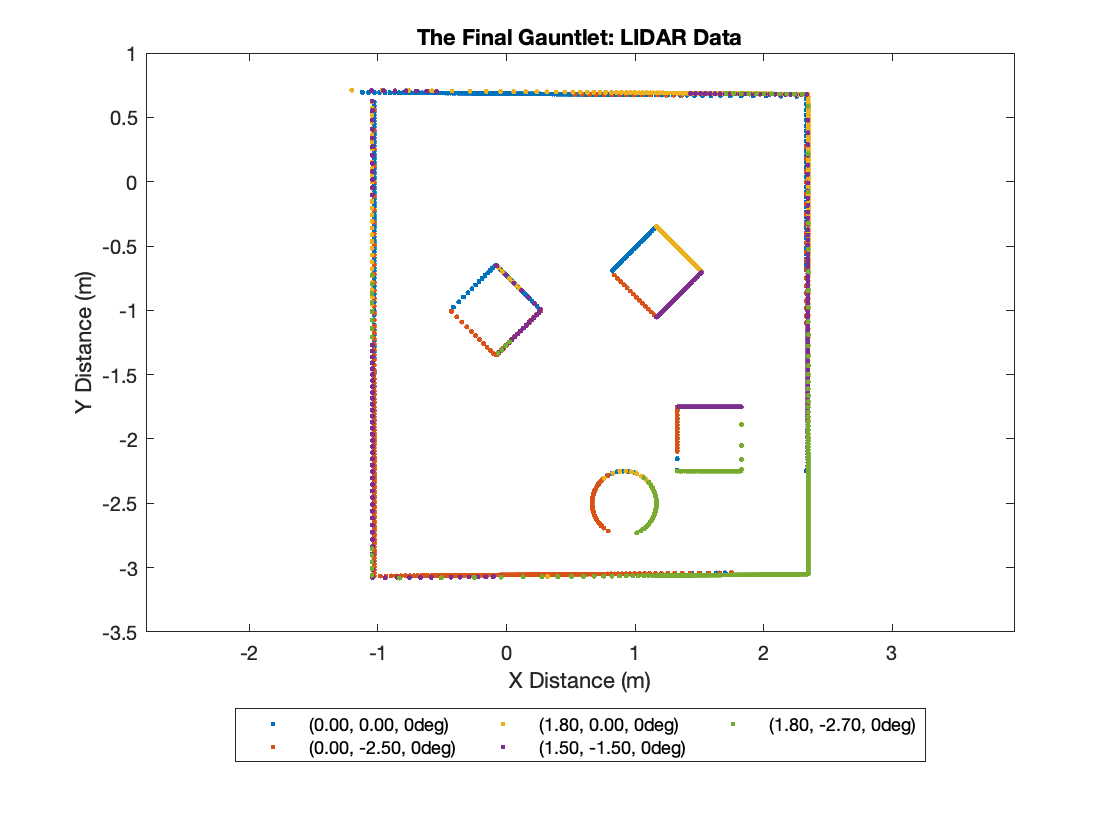

load('scans/lidar2.mat', 'lidar_results', 'lidar_positions');
% lidar.mat has a lidar matrix which is n x 2 x m, where each (:, :, m) is
% one scan in the form of [r, theta], where r and theta are column vectors.
% It also has a 3 x m matrix of column vectors of the format [x, y, phi],
% representing the position and orientation of the Neato when each scan was
% taken.

clf; figure(1);

for i=1:size(lidar_results, 3)
    r_G = to_global(lidar_results(:, 1, i), lidar_results(:, 2, i), lidar_positions(i, 1:2), lidar_positions(i, 3));
    label = sprintf("(%1.2f, %1.2f, %1.0fdeg)", lidar_positions(i, 1), lidar_positions(i, 2), lidar_positions(i, 3));
    plot(r_G(:, 1), r_G(:, 2), '.', 'DisplayName', label); hold on;
end

title("The Final Gauntlet: LIDAR Data");
xlabel("X Distance (m)");
ylabel("Y Distance (m)");
xlim([-1.5, 3]);
ylim([-3.5, 1]);

legend show;
lgnd = legend;
lgnd.Location = 'southoutside';
lgnd.NumColumns = 3;

axis equal;

hold off;

**Figure 1.** LIDAR-generated map of the Gauntlet, composed of multiple LIDAR scans. Each scan is represented with a different color.

### Strategy

#### Creating The Potential Field

To create the potential field that represents the pen's obstacles and target, we translated provided information about obstacles and the Barrel of Benevolence into a series of point sources. The square (technically rectangular prisim) obstacles were represented with point sources at each corner and in the center, while the circular (technically cylindrical) Barrel of Benevolence was represented by a single point sink at its center. The walls were each represented by infinitely long line sources.

For the squares, we used the following process to calculate their corner points:

- Given that each square obstacle has a side length, $s$, an angle, $\theta$, and a center point, $$\left(x,y\right)$$, the a matrix of points representing the corners of a square with the same side length centered at $$\left(0,0\right)$$ rotated 0 degrees can be represented as the following: 


$$\left\lbrack \begin{array}{cccc}
\frac{s}{2} & -\frac{s}{2} & -\frac{s}{2} & \frac{s}{2}\\
\frac{s}{2} & \frac{s}{2} & -\frac{s}{2} & -\frac{s}{2}\\
1 & 1 & 1 & 1
\end{array}\right\rbrack$$


This matrix can be transformed to represent the actual endpoints of the obstacles my multiplying it by a rotation matrix and then a translation matrix:


$$P=\left\lbrack \begin{array}{ccc}
1 & 0 & x\\
0 & 1 & y\\
0 & 0 & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & -\sin \left(\theta \right) & 0\\
\sin \left(\theta \right) & \cos \left(\theta \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{cccc}
\frac{s}{2} & -\frac{s}{2} & -\frac{s}{2} & \frac{s}{2}\\
\frac{s}{2} & \frac{s}{2} & -\frac{s}{2} & -\frac{s}{2}\\
1 & 1 & 1 & 1
\end{array}\right\rbrack$$


Next, we created the potential field. To do this, we started by creating potential fields for each object. Each point source for an obstacle was generated using the following formula (where $\left(a,b\right)$ is the location of the point source):


$$\ln \left(\sqrt{{\left(x-a\right)}^2 +{\left(y-b\right)}^2 }\right)$$


The line sources for the walls were generated as follows (where $a$ and $b$ are the x and y positions of the lines, respectively):

Vertical lines: $\ln \left(\sqrt{{\left(x-a\right)}^2 }\right)$, horizontal lines: $\ln \left(\sqrt{{\left(y-b\right)}^2 }\right)$

The point sink for the Barrel of Benevolence was generated as follows (notice the negative sign representing a sink):


$$-\ln \left(\sqrt{{\left(x-a\right)}^2 +{\left(y-b\right)}^2 }\right)$$


The potential fields for each element were lineraly combined, with obstacles being scaled by $0\ldotp 02$, walls by $0\ldotp 04$, and the Barrel of Benevolence by $0\ldotp 6$. Once the final potential field was created, its gradient was also computed. These computations and the resulting 3D/contour plots can be seen below.

% Generate the potential field

syms X Y; % our axes

wall = ...
    log(sqrt((Y + 3.37) .^ 2)) + ...
    log(sqrt((Y - 1.00) .^ 2)) + ...
    log(sqrt((X + 1.50) .^ 2)) + ...
    log(sqrt((X - 2.50) .^ 2));

% format is [center x, center y, angle, side length]
obstacle_info = [
    -0.25, -1.0, pi/4, 0.5;
     1.41, -2.0,    0, 0.5;
     1.00, -0.7, pi/4, 0.5
];

bucket_x = 0.75;
bucket_y = -2.5;
bucket_r = 0.25;

obstacles = 0; % this will become a symbolic expression representing the obstacles
corners = []; % 4x2xn, with one 4x2 for each obstacle (one row per corner, [x y] format)

for i=1:size(obstacle_info, 1)
    % add a source for the center
    obstacles = obstacles + ...
        log(sqrt((X - obstacle_info(i, 1)) .^ 2 + (Y - obstacle_info(i, 2)) .^ 2));
    
    % store corner positions
    corners(:, :, i) = squareToCorners(obstacle_info(i, 1), obstacle_info(i, 2), obstacle_info(i, 3), obstacle_info(i, 4));
    
    % add a source for each corner
    for j=1:size(corners, 1)
        obstacles = obstacles + ...
            log(sqrt((X - corners(j, 1, i)) .^ 2 + (Y - corners(j, 2, i)) .^ 2));
    end
end

% assemble it all into one symbolic expression
Z = (0.02 * obstacles) ...
    + (0.04 * wall) ...
    - (0.6 * log(sqrt((X - bucket_x) .^ 2 + (Y - bucket_y) .^ 2)));

% convert the function (and its gradient) into non-symbolic MATLAB
% functions for performance
f = matlabFunction(Z);
grad = matlabFunction(gradient(Z));

disp("Our Potential Field Equation:");

Our Potential Field Equation:


potential_field = Z

$$potential\_field = 0.0200\,\log\left(\sqrt{{\left(X-0.6464\right)}^{2}+{\left(Y+0.7000\right)}^{2}}\right)-0.6000\,\log\left(\sqrt{{\left(Y+2.5000\right)}^{2}+{\left(X-0.7500\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1.3536\right)}^{2}+{\left(Y+0.7000\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+2.2500\right)}^{2}+{\left(X-1.6600\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1.1600\right)}^{2}+{\left(Y+1.7500\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(X-2.5000\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1.6600\right)}^{2}+{\left(Y+1.7500\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(X+1.5000\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(Y+3.3700\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+1\right)}^{2}+{\left(X+0.2500\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1\right)}^{2}+{\left(Y+1.0536\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+1\right)}^{2}+{\left(X+0.6036\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1\right)}^{2}+{\left(Y+0.3464\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1\right)}^{2}+{\left(Y+0.7000\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+2\right)}^{2}+{\left(X-1.4100\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+1\right)}^{2}+{\left(X-0.1036\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(Y-1\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+2.2500\right)}^{2}+{\left(X-1.1600\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X+0.2500\right)}^{2}+{\left(Y+0.6464\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X+0.2500\right)}^{2}+{\left(Y+1.3536\right)}^{2}}\right)$$

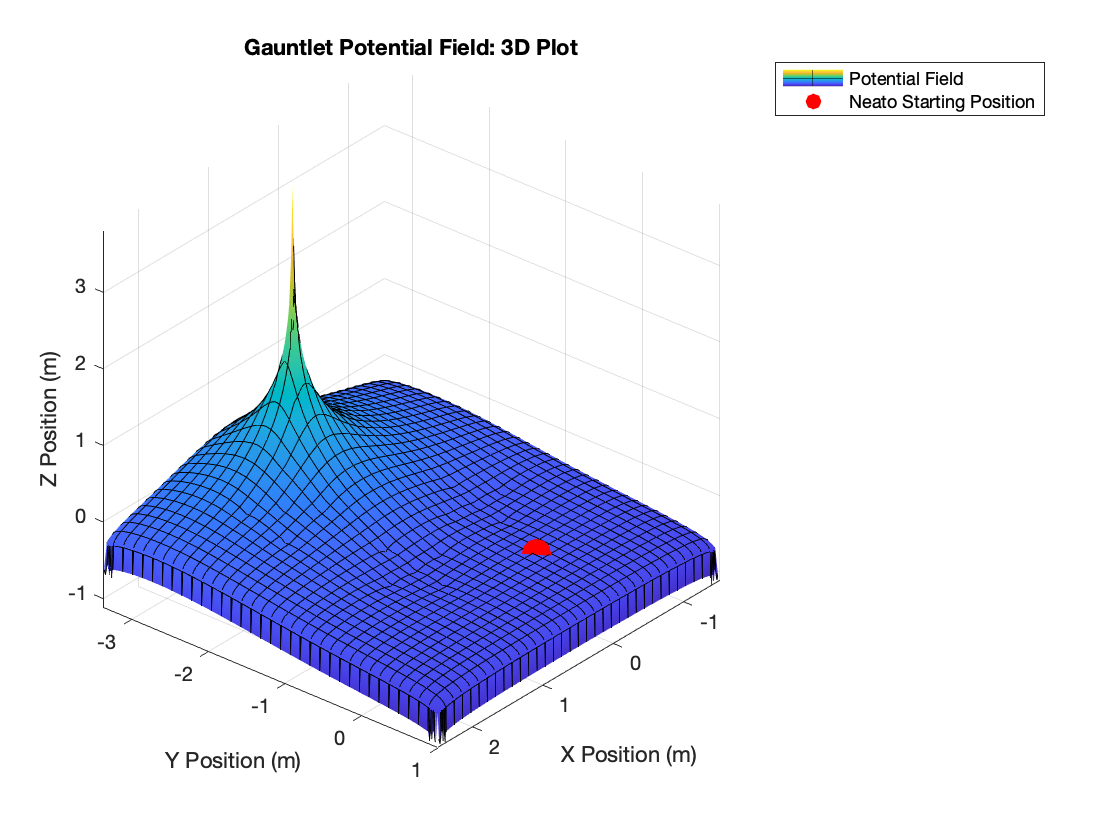


% Plot a contour plot
figure(2); clf;

fsurf(f, [-1.5, 2.5, -3.37, 1]); hold on;
plot3(0, 0, f(0, 0), 'r.', 'MarkerSize', 50);
xlim([-1.5, 2.5]); ylim([-3.37, 1]); view([-230, 30]);
xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");
legend("Potential Field", "Neato Starting Position");
title("Gauntlet Potential Field: 3D Plot");
hold off;

**Figure 2.** A 3D plot of our potential field.

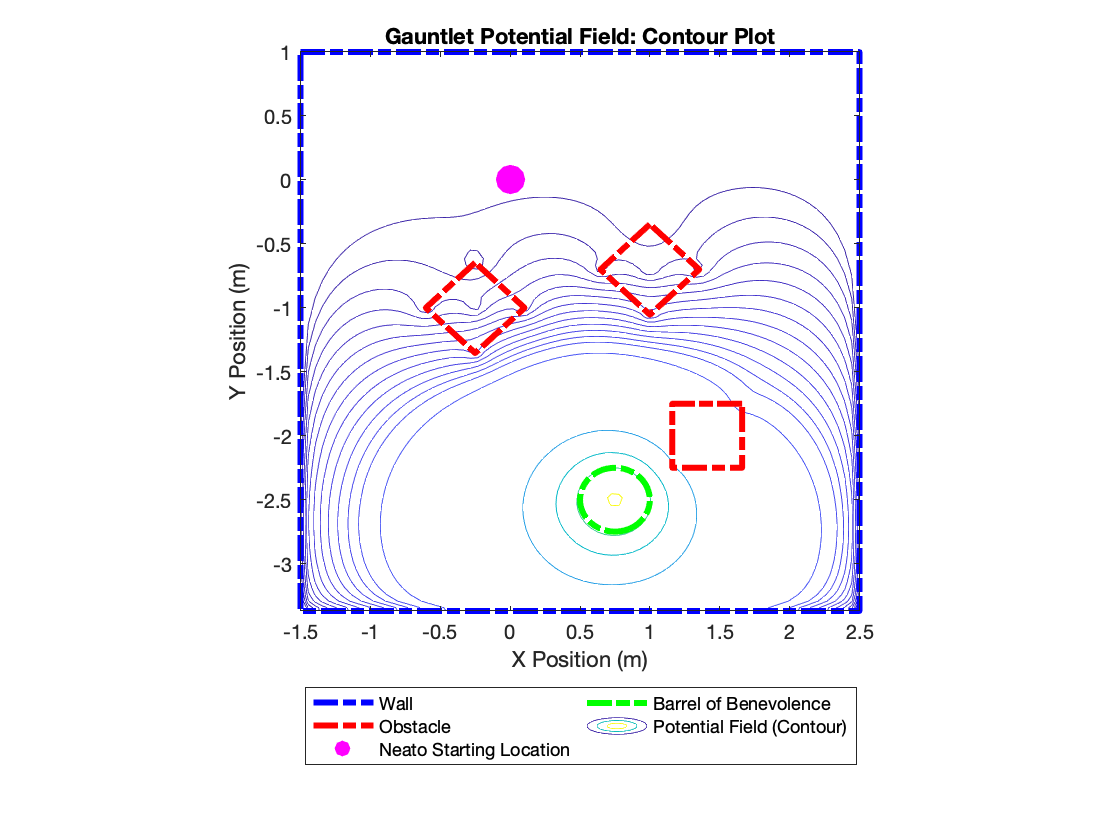

figure(3); clf;

% MATLAB has a function (fcontour) which plots the contours of a function,
% but it doesn't let you specify levels, which results in missed nuance
% here, so we have to do things the ol' fashion way.
[x, y] = meshgrid(linspace(-2, 3), linspace(-4, 1));
z = f(x, y);
[~, pcontour] = contour(x, y, z, [0, -0.05:-0.025:-.35, .5, .75, 1, 2, 5]);

xlim([-1.5, 2.5]); ylim([-3.37, 1]);
xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");
axis square; hold on;

wallpts = [
    -1.5, 1;
     2.5, 1;
     2.5, -3.37;
    -1.5, -3.37;
    -1.5, 1; % last point repeated to get a closed box
];

pwall = plot(wallpts(:, 1), wallpts(:, 2), 'b-.', 'LineWidth', 3);

for i=1:size(corners, 3)
    pts = [corners(:, :, i); corners(1, :, i)]; % we add the first point again to the end to get a closed box
    pobstacle = plot(pts(:, 1), pts(:, 2), 'r-.', 'LineWidth', 3);
end

pbucket = fimplicit(@(x, y) ((x - bucket_x).^2 + (y - bucket_y).^2 - bucket_r.^2), 'g-.', 'LineWidth', 3);
pneato = plot(0, 0, 'm.', 'MarkerSize', 50);
lgnd = legend([pwall, pobstacle, pneato, pbucket, pcontour], {"Wall", "Obstacle", "Neato Starting Location", "Barrel of Benevolence", "Potential Field (Contour)"});
lgnd.Location = 'southoutside';
lgnd.NumColumns = 2;
title("Gauntlet Potential Field: Contour Plot");

**Figure 3.** A contour plot of our potential field.

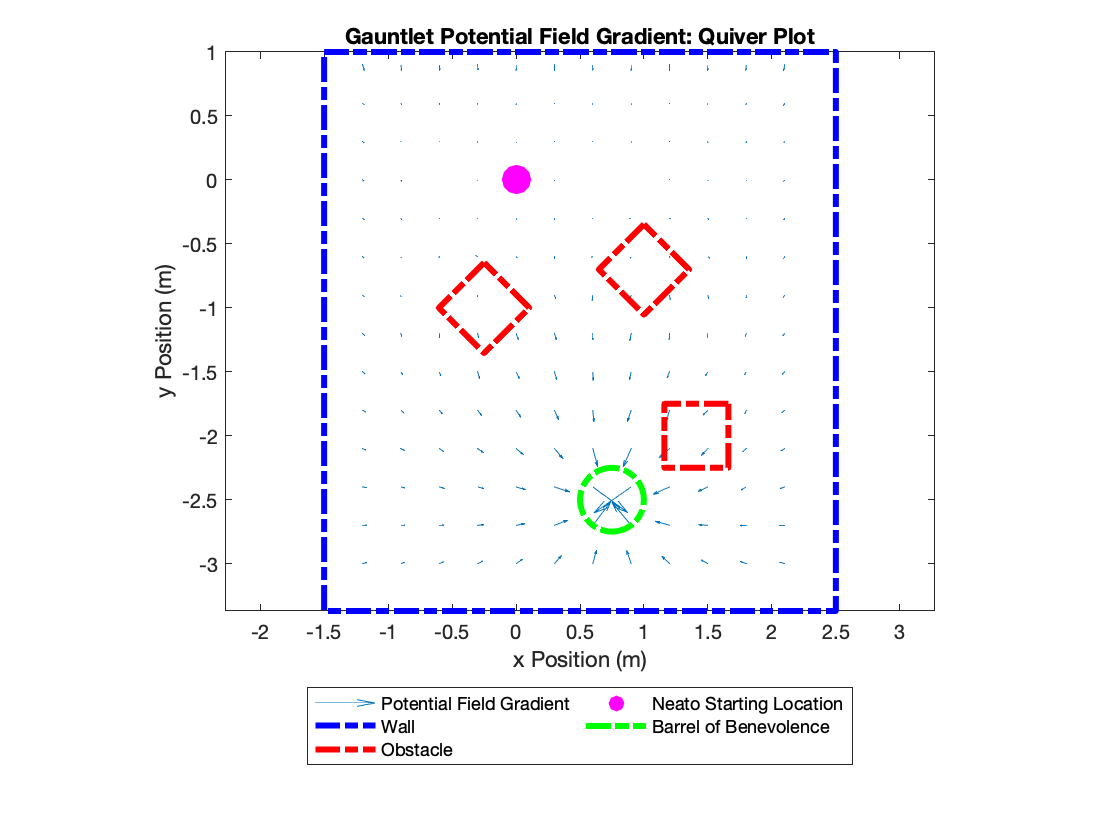

[x,y] = meshgrid(-1.2:0.3:2.2, -3:0.3:1);

x = reshape(x, [1, numel(x)]);
y = reshape(y, [1, numel(y)]);

g = grad(x, y);

figure(4); clf;
pquiver = quiver(x, y, g(1, :), g(2, :)); hold on;
axis equal;
xlabel('x Position (m)')
ylabel('y Position (m)')
wallpts = [
    -1.5, 1;
     2.5, 1;
     2.5, -3.37;
    -1.5, -3.37;
    -1.5, 1; % last point repeated to get a closed box
];

pwall = plot(wallpts(:, 1), wallpts(:, 2), 'b-.', 'LineWidth', 3);

for i=1:size(corners, 3)
    pts = [corners(:, :, i); corners(1, :, i)]; % we add the first point again to the end to get a closed box
    pobstacle = plot(pts(:, 1), pts(:, 2), 'r-.', 'LineWidth', 3);
end

pbucket = fimplicit(@(x, y) ((x - bucket_x).^2 + (y - bucket_y).^2 - bucket_r.^2), 'g-.', 'LineWidth', 3);
pneato = plot(0, 0, 'm.', 'MarkerSize', 50);
lgnd = legend([pquiver, pwall, pobstacle, pneato, pbucket], {"Potential Field Gradient", "Wall", "Obstacle", "Neato Starting Location", "Barrel of Benevolence"});
lgnd.Location = 'southoutside';
lgnd.NumColumns = 2;
title("Gauntlet Potential Field Gradient: Quiver Plot");
hold off;

**Figure 4.** A quiver plot of the gradient of our potential field.

#### Gradient Ascent

After obtaining the gradient of the potential field, the path for gradient ascent can be calculated. If the potential field is represented as $$f(r)$$, a function of a position vector, the points for each step of gradient are given by the equation,


$$$r_{i+1}=r_i+\lambda_i\nabla{}f(r_i),   i=1,2,3,...$$$


where $\lambda_i$ is the relative step size for the distance moved in the direction of the gradient. In this case, it is calculated at each step with the equation,


$$$\lambda_{i+1}=\delta\lambda_i$$$


The initial values for $\lambda$ and $\delta$ (1 and 0.9554, respectively) were chosen based on the steepness of the slope and the change in steepness of the slope.

Once all of the points for the descent are calculated, the linear, angular, and wheel velocities that the Neato will need to execute are calculated and stored to a file, along with the relevant timestamps. A companion script run inside the simulator (`neato.m`) reads these commands and executes them.

***Author's Note:**** As strange as it sounds, we found our gradient ascent algorithm to be non-deterministic (specifically, we think this is due to either a bug or an imprecision in MATLAB's Symbolic Toolbox). As a result, running ****exactly**** the same code (as verified by Git) sometimes produces a very nice, smooth path and sometimes produces a horrible zig-zag. We used the smooth path in the simulator, but unfortunately weren't able to reproduce it for the purposes of this report (we literally spent hours trying). So, here's what we've done: ****Figure 5**** below shows the smooth path that our Neato actually took. It was generated by exactly the same code, with exactly the same parameters as ****Figure 6****, which shows the horrible zig-zaggy path that MATLAB has decided to give us now. We have no idea why the figures aren't identical, but they aren't. We hope that together, they demonstrate that we did successfully accomplish the assignment. Unfortunately, the only version of ****Figure 5**** that we could recover was a screenshot from before we polished up the graphs for this report—so it's lacking things like a title and legend. While we know that's not ideal, it's the best we could do under these circumstances. We thank you for your understanding.*

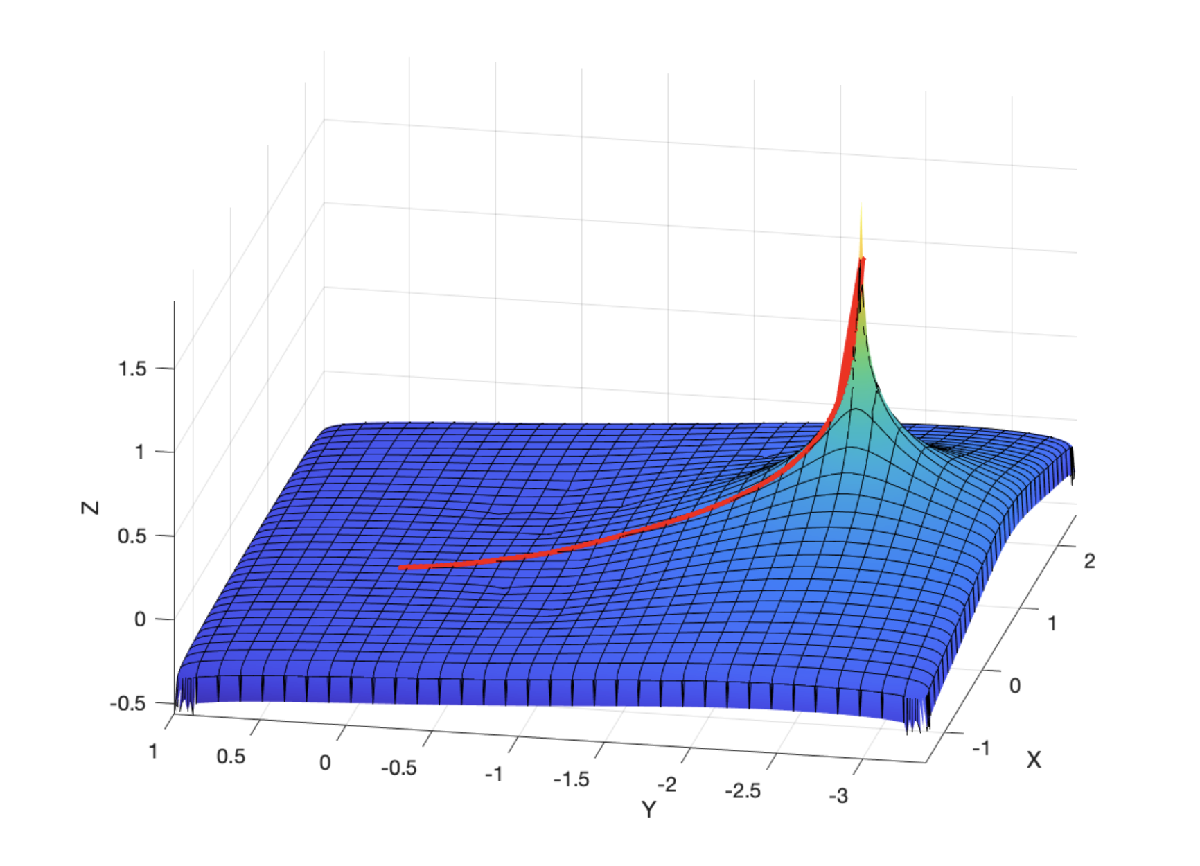

**Figure 5.** A forensically-recovered pre-publication plot of the gradient ascent path that our Neato actually took.

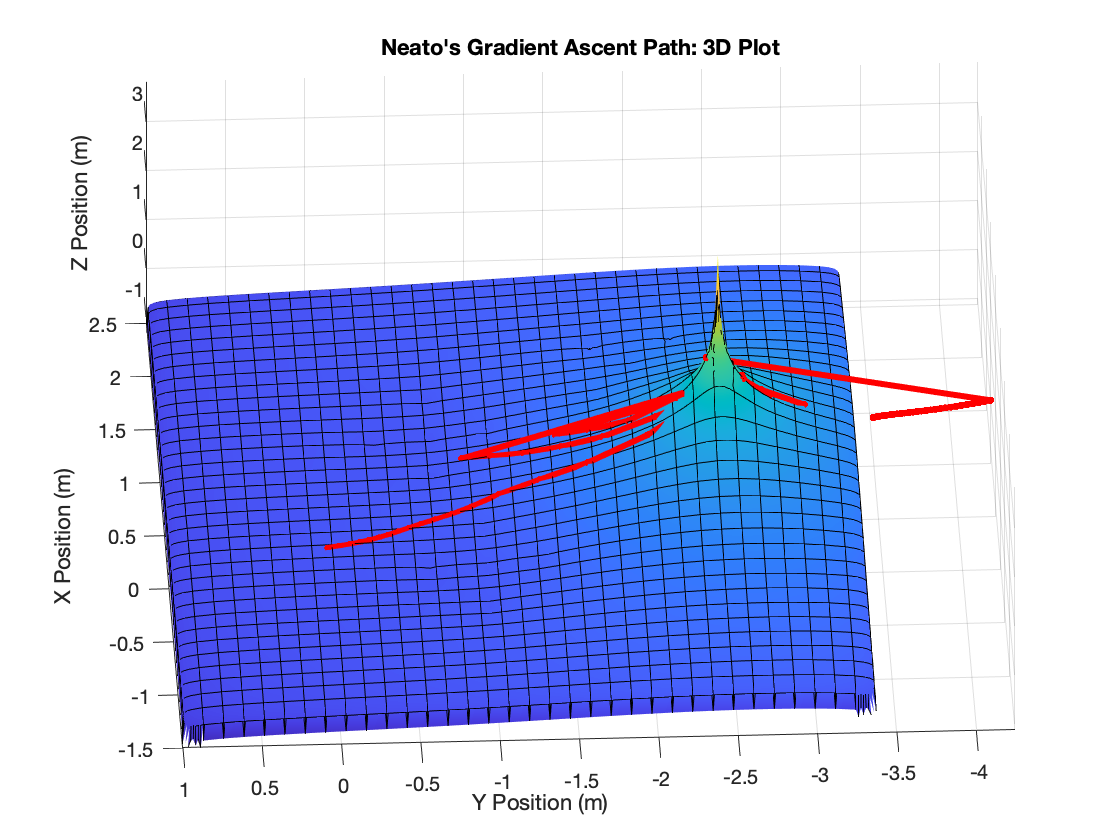

[positions, headings] = gradient_ascent(grad, [0, 0], [1, 0], 1, .9554, .01, 1000); % run gradient ascent

figure(6); clf;
fsurf(f, [-1.5, 2.5, -3.37, 1]); hold on;
plot3(positions(:, 1), positions(:, 2), f(positions(:, 1), positions(:, 2)), 'r.-', 'LineWidth', 3, "MarkerSize", 10);
title("Neato's Gradient Ascent Path: 3D Plot");
view([-130 15]); xlim([-1.5, 2.5]); ylim([-3.37, 1]);
xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");

**Figure 6.** A properly-formatted 3D plot representing *a* gradient ascent path, although not the one our Neato actually took. This plot serves to demonstrate our ability to produce a nice, properly-formated figure of a gradient ascent plot when MATLAB is willing to cooperate.

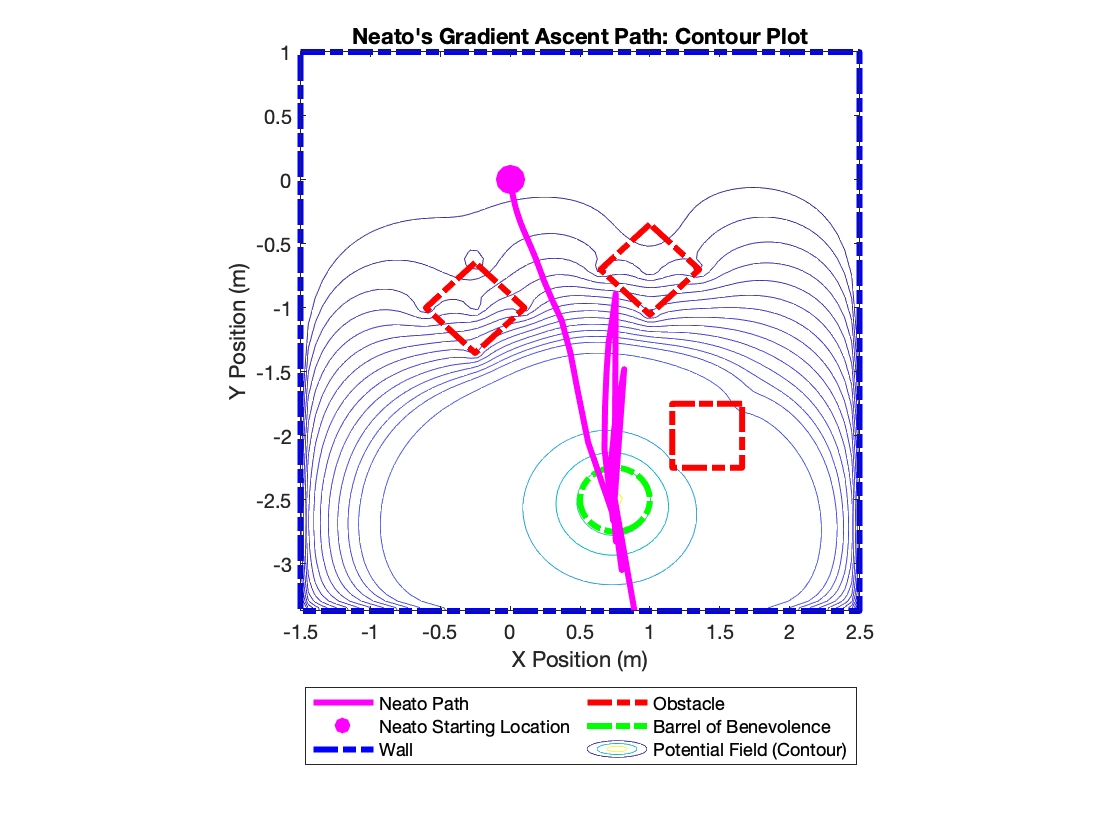

figure(7); clf;

% MATLAB has a function (fcontour) which plots the contours of a function,
% but it doesn't let you specify levels, which results in missed nuance
% here, so we have to do things the ol' fashion way.
[x, y] = meshgrid(linspace(-2, 3), linspace(-4, 1));
z = f(x, y);
[~, pcontour] = contour(x, y, z, [0, -0.05:-0.025:-.35, .5, .75, 1, 2, 5]);

xlim([-1.5, 2.5]); ylim([-3.37, 1]);
xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");

axis square; hold on;

wallpts = [
    -1.5, 1;
     2.5, 1;
     2.5, -3.37;
    -1.5, -3.37;
    -1.5, 1; % last point repeated to get a closed box
];

pwall = plot(wallpts(:, 1), wallpts(:, 2), 'b-.', 'LineWidth', 3);

for i=1:size(corners, 3)
    pts = [corners(:, :, i); corners(1, :, i)]; % we add the first point again to the end to get a closed box
    pobstacle = plot(pts(:, 1), pts(:, 2), 'r-.', 'LineWidth', 3);
end

pbucket = fimplicit(@(x, y) ((x - bucket_x).^2 + (y - bucket_y).^2 - bucket_r.^2), 'g-.', 'LineWidth', 3);
pneato = plot(0, 0, 'm.', 'MarkerSize', 50);
ppath = plot(positions(:, 1), positions(:, 2), 'm-', 'LineWidth', 3);
lgnd = legend([ppath, pneato, pwall, pobstacle, pbucket, pcontour], {"Neato Path", "Neato Starting Location", "Wall", "Obstacle", "Barrel of Benevolence", "Potential Field (Contour)"});
lgnd.Location = 'southoutside';
lgnd.NumColumns = 2;
title("Neato's Gradient Ascent Path: Contour Plot");

**Figure 7.** A properly-formatted contour plot representing *a* gradient ascent path, although not the one our Neato actually took. This plot serves to demonstrate our ability to produce a nice, properly-formated figure of a gradient ascent plot when MATLAB is willing to cooperate.

## Results

The Neato successfully traversed the gauntlet in 91 seconds, traveling 2.1 meters on its journey before arriving at the Barrel of Benevolence. The path that the simulated NEATO took is shown in the plot below. 

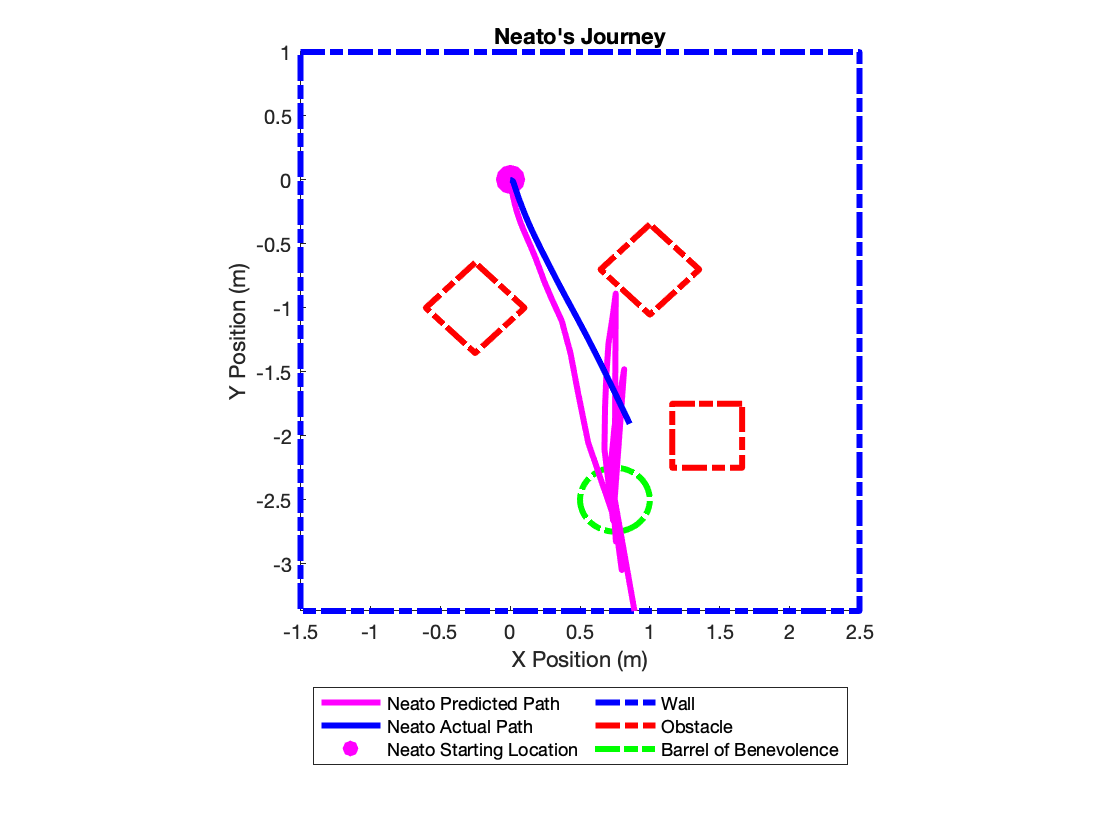

figure(8); clf;
% We load our saved encoder data from when we ran our code in the simulator
% This odometry code is taken from our Bridge of Doom (dun dun dun) assignment.
% We worked together for that project too.
load("encoder_data.mat");
d = 0.235; % m, wheelbase of the Neato

%% The stored encoder data gives us total time and distance, but we also
%% need the relative changes in each sample--so we calculate that here:
enc_dt = diff(enc_t);
enc_dl = diff(enc_l) ./ enc_dt;
enc_dr = diff(enc_r) ./ enc_dt;

%% We also need to derive the wheel, linear, and angular velocities from the
%% measured encoder values.

% Define our symbolic variables
syms vl vr vlin vrot;
assume(vl, 'real');
assume(vr, 'real');
assume(vlin, 'real');
assume(vrot, 'real');

% Define our equations
vl_eqn = vl == vlin - (vrot .* (d ./ 2));
vr_eqn = vr == vlin + (vrot .* (d ./ 2));

% Have MATLAB solve them
[vrot, vlin] = solve([vl_eqn, vr_eqn], [vrot, vlin]);

% Substitute in our data and calculate the answers
vl = enc_dl;
vr = enc_dr;
vrots = double(subs(vrot));
vlins = double(subs(vlin));

%% Finally, we need to calculate the actual path that the robot took from these
%% encoder values

% Define our variables
enc_thetas = zeros(length(enc_t), 1);
enc_rxs = zeros(length(enc_t), 1);
enc_rys = zeros(length(enc_t), 1);

% We need to calculate our initial values differently, because encoders--by
% definition--cannot tell you your starting position. For that, we the
% predefined starting position. That's OK because the first command of the Neato's
% actual program is to use the magic of the simulator to move the neato to
% the starting position perscribed by the calculated solution.
that_0 = [1 0];
enc_thetas(1) = atan(that_0(2)/that_0(1));
enc_rxs(1) = 0;
enc_rys(1) = 0;

total_dist = 0;

% Then iteratively calculate each subsequent heading and position
for i=1:length(enc_dt)
    enc_thetas(i + 1) = enc_thetas(i) + (vrots(i) * enc_dt(i));
    
    drx = (vlins(i) * cos(enc_thetas(i + 1)) * enc_dt(i));
    dry = (vlins(i) * sin(enc_thetas(i + 1)) * enc_dt(i));
    dist = norm([drx, dry]);
    
    enc_rxs(i + 1) = enc_rxs(i) + drx;
    enc_rys(i + 1) = enc_rys(i) + dry;
    
    if ~isnan(dist)
        total_dist = total_dist + dist;
    end
end

% Finally, calculate the Thats and Nhats from the headings
% We could technically optimize this step since we already do this math
% inside the loop, but Keep-It-Simple-Stupid/"premature optimization is the
% root of all evil"/etc.
enc_Thats = [cos(enc_thetas), sin(enc_thetas)];
enc_Nhats = [-cos(enc_thetas), -sin(enc_thetas)];

xlim([-1.5, 2.5]); ylim([-3.37, 1]);
xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");

axis square; hold on;

wallpts = [
    -1.5, 1;
     2.5, 1;
     2.5, -3.37;
    -1.5, -3.37;
    -1.5, 1; % last point repeated to get a closed box
];

pwall = plot(wallpts(:, 1), wallpts(:, 2), 'b-.', 'LineWidth', 3);

for i=1:size(corners, 3)
    pts = [corners(:, :, i); corners(1, :, i)]; % we add the first point again to the end to get a closed box
    pobstacle = plot(pts(:, 1), pts(:, 2), 'r-.', 'LineWidth', 3);
end

pbucket = fimplicit(@(x, y) ((x - bucket_x).^2 + (y - bucket_y).^2 - bucket_r.^2), 'g-.', 'LineWidth', 3);
pneato = plot(0, 0, 'm.', 'MarkerSize', 50);

ppredicted = plot(positions(:, 1), positions(:, 2), 'm-', 'LineWidth', 3);
pactual = plot(enc_rxs, enc_rys, 'b-', 'LineWidth', 3);
lgnd = legend([ppredicted, pactual, pneato, pwall, pobstacle, pbucket], {"Neato Predicted Path", "Neato Actual Path", "Neato Starting Location", "Wall", "Obstacle", "Barrel of Benevolence"});
lgnd.Location = 'southoutside';
lgnd.NumColumns = 2;
title("Neato's Journey");

fprintf("The Neato traveled %2.2fm meters over the course of its journey.", total_dist);

The Neato traveled 2.10m meters over the course of its journey.

**Figure 8.** A plot showing the obstacles and Barrel of Benevolence and the Neato's actual and predicted paths (see the above caveat for why the predicted path is very different from the actual one).